# Image Quality Analysis and Visualization

Ensure required toolboxes and libraries are installed before running. Image Processing Toolbox is needed.

clc; clear; close all;

## Task 2: Image Distortion Visualization (Blur, Noise, Compression Artifacts)

Load sample image

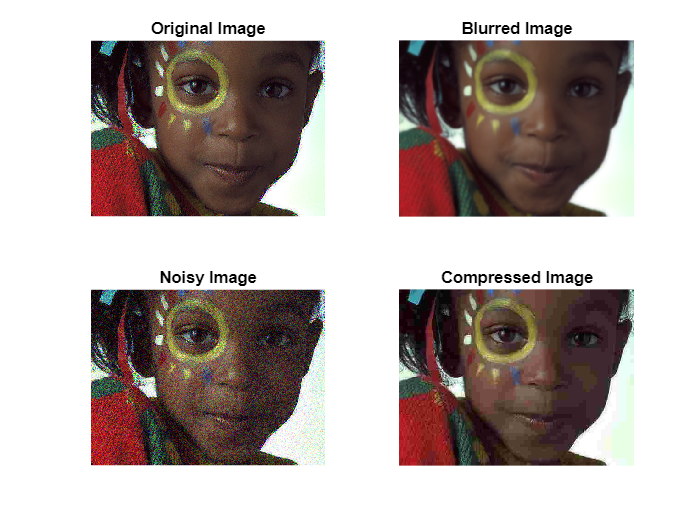

originalImage = imread('image1.png');

% Blur (Gaussian Blur)
blurredImage = imgaussfilt(originalImage, 2);

% Add noise (Gaussian noise)
noisyImage = imnoise(originalImage, 'gaussian', 0, 0.01);

% Compression artifacts (using imwrite JPEG compression)
imwrite(originalImage, 'compressed.jpg', 'Quality', 10);
compressedImage = imread('compressed.jpg');

% Visualization
figure;
subplot(2,2,1); imshow(originalImage); title('Original Image');
subplot(2,2,2); imshow(blurredImage); title('Blurred Image');
subplot(2,2,3); imshow(noisyImage); title('Noisy Image');
subplot(2,2,4); imshow(compressedImage); title('Compressed Image');

## Task 3: Objective Quality Metrics (PSNR, SSIM)

PSNR and SSIM Comparisons

psnr_blur = psnr(blurredImage, originalImage);
psnr_noise = psnr(noisyImage, originalImage);
psnr_compressed = psnr(compressedImage, originalImage);

ssim_blur = ssim(blurredImage, originalImage);
ssim_noise = ssim(noisyImage, originalImage);
ssim_compressed = ssim(compressedImage, originalImage);

fprintf('PSNR Values: Blur = %.2f, Noise = %.2f, Compression = %.2f\n', ...
    psnr_blur, psnr_noise, psnr_compressed);

PSNR Values: Blur = 23.09, Noise = 20.64, Compression = 22.89


fprintf('SSIM Values: Blur = %.2f, Noise = %.2f, Compression = %.2f\n', ...
    ssim_blur, ssim_noise, ssim_compressed);

SSIM Values: Blur = 0.79, Noise = 0.53, Compression = 0.75


## Task 4: Blind Image Quality Metrics (BRISQUE, NIQE)

brisque_score = brisque(originalImage);
niqe_score = niqe(originalImage);

fprintf('BRISQUE Score = %.2f, NIQE Score = %.2f\n', brisque_score, niqe_score);

BRISQUE Score = 37.93, NIQE Score = 14.90


## Task 5: Texture Analysis (Haralick Features, Gabor Filters)

Haralick Features (using graycomatrix)

grayImage = rgb2gray(originalImage);
glcMatrix = graycomatrix(grayImage, 'Offset', [0 1]);
stats = graycoprops(glcMatrix, {'contrast', 'correlation', 'energy', 'homogeneity'});
disp(stats);

       Contrast: 0.4798
    Correlation: 0.9392
         Energy: 0.1498
    Homogeneity: 0.8599




% Gabor Filter Application
gaborArray = gabor([4 8], [0 90]);
gaborMag = imgaborfilt(grayImage, gaborArray);

## Task 6: Sharpness Analysis using Laplacian

% laplacianSharpness = var(double(del2(grayImage)));
laplacianSharpness = var(double(del2(double(grayImage))));

if laplacianSharpness < 10
    disp('The image is too blurry.');
else
    disp('The image is adequately sharp.');
end

The image is adequately sharp.


## Task 7: Color Analysis (Histograms)

Compute and plot histograms in RGB, HSV, LAB spaces

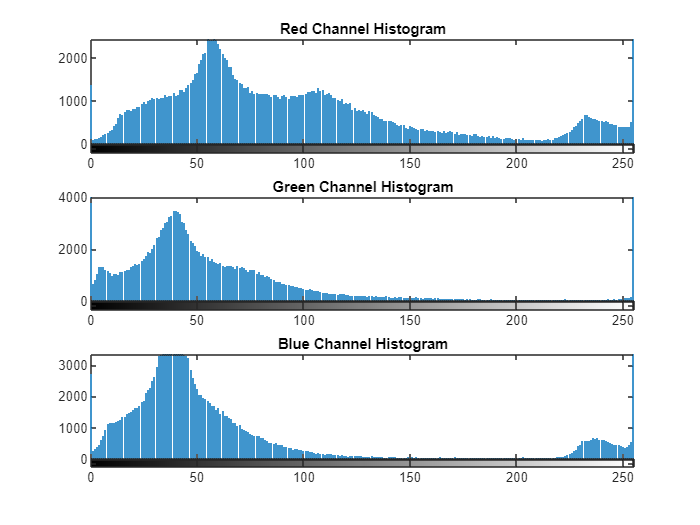

figure;
subplot(3,1,1); imhist(originalImage(:,:,1)); title('Red Channel Histogram');
subplot(3,1,2); imhist(originalImage(:,:,2)); title('Green Channel Histogram');
subplot(3,1,3); imhist(originalImage(:,:,3)); title('Blue Channel Histogram');

## Task 8: Contrast Analysis (Michelson and Weber Metrics)

maxIntensity = double(max(grayImage(:)));
minIntensity = double(min(grayImage(:)));
michelsonContrast = (maxIntensity - minIntensity) / (maxIntensity + minIntensity);

weberContrast = (maxIntensity - mean(grayImage(:))) / mean(grayImage(:));

fprintf('Michelson Contrast: %.2f, Weber Contrast: %.2f\n', michelsonContrast, weberContrast);

Michelson Contrast: 1.00, Weber Contrast: 2.15


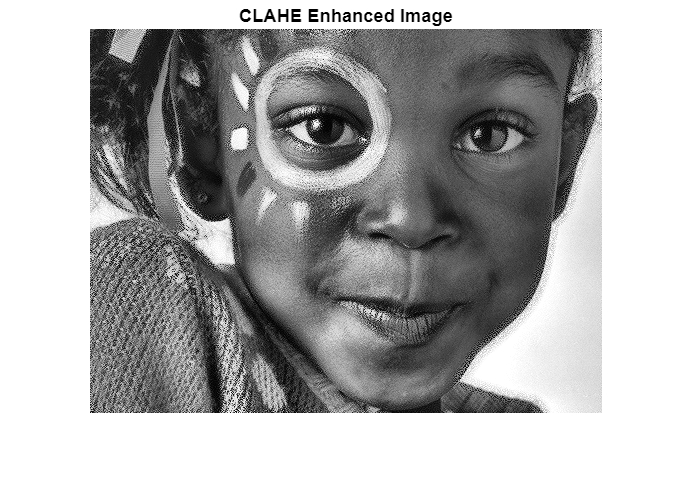


% CLAHE for contrast enhancement
claheImage = adapthisteq(grayImage);
figure; imshow(claheImage); title('CLAHE Enhanced Image');

## Task 9: Machine Learning Model for Quality Prediction

Assume features are computed (from BRISQUE, NIQE, etc.)

features = [brisque_score niqe_score laplacianSharpness michelsonContrast weberContrast; 
            brisque_score+1 niqe_score+0.5 laplacianSharpness-0.2 michelsonContrast+0.1 weberContrast-0.1;
            brisque_score-0.5 niqe_score+0.2 laplacianSharpness+0.1 michelsonContrast-0.05 weberContrast+0.3];

labels = [1; 2; 3]; % Corresponding quality classes
model = fitrensemble(features, labels);

## Task 10: Clustering

K-means Clustering Example

k = 3;
[idx, C] = kmeans(features', k);

## Task 11: Neural Network Transfer Learning

Load a pre-trained network (VGG16)

try
    net = vgg16('Weights', 'none');
    fprintf('VGG16 Model loaded successfully.\n');
catch
    fprintf('VGG16 model is not available.\n');
end

VGG16 Model loaded successfully.


## Task 12: Autoencoder for Image Restoration

Define an example autoencoder for image restoration

inputSize = size(originalImage);
encoderLayers = [imageInputLayer(inputSize)
    convolution2dLayer(3,8,'Padding','same')
    reluLayer()
    maxPooling2dLayer(2,'Stride',2)];

## Task 13: Automated Folder Analysis Function

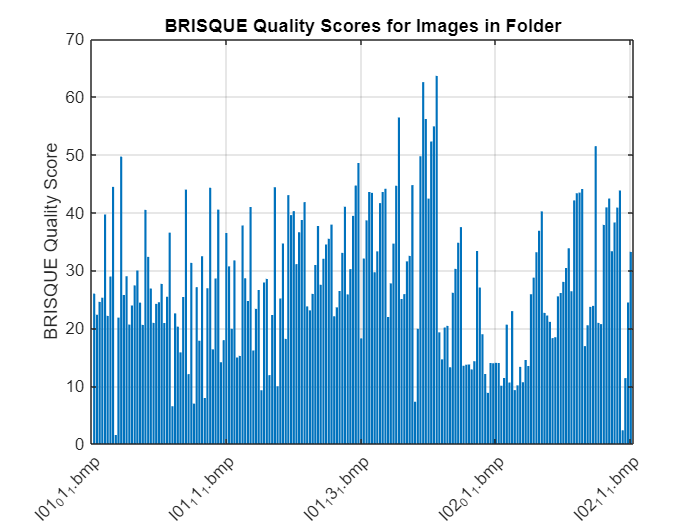

function qualityAnalysisReport(folderPath)
    files = dir(fullfile(folderPath, '*.bmp'));
    fileCount = 200;
    scores = zeros(1, fileCount); % Store BRISQUE scores
    fileNames = strings(1, fileCount);

    for k = 1:fileCount
        imgPath = fullfile(folderPath, files(k).name);
        img = imread(imgPath);
        quality = brisque(img);
        scores(k) = quality;
        fileNames(k) = files(k).name;
    end

    % Plot the BRISQUE scores
    figure;
    bar(scores);
    set(gca, 'XTickLabel', fileNames, 'XTickLabelRotation', 45);
    ylabel('BRISQUE Quality Score');
    title('BRISQUE Quality Scores for Images in Folder');
    grid on;
end

qualityAnalysisReport('C:\Users\austeja.rusenaite\Desktop\tid2013\distorted_images')

## Task 14: Interactive Interface (Gradio or Streamlit Alternative)

-